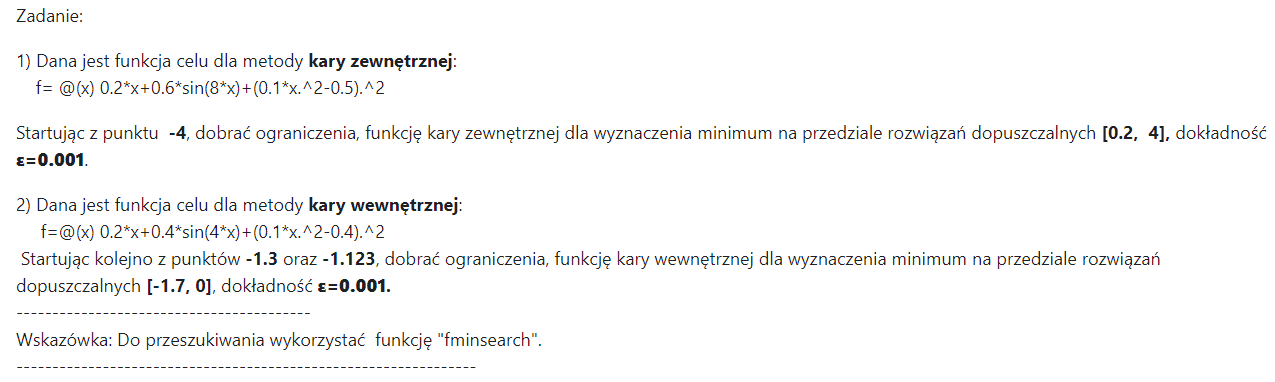


clear;
f = @(x) 0.2 * x + 0.6 * sin(8 * x) + (0.1 * x ^ 2 - 0.5) ^ 2;
x0 = -4; eps = 0.001; ogr = [0.2 4]; c0 = 2;

figure; fplot(f); hold on; grid on;

xline(ogr(1), 'r');
xline(ogr(2), 'r');
plot(x0, f(x0), 'ro', "MarkerSize", 7, "MarkerFace", "r");

[zew_min, iter] = kar_zew(f, x0, c0, ogr(1), ogr(2), eps)

zew_min = 2.1554

iter = 3

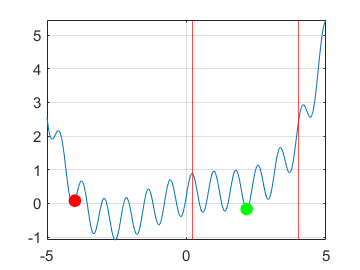


plot(zew_min, f(zew_min), 'go', "MarkerSize", 7, "MarkerFace", "g");
hold off;

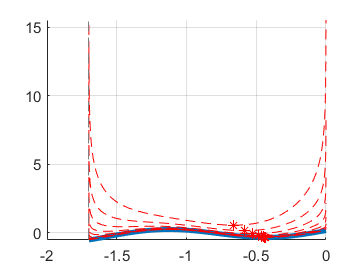

zew_min = -0.4355

iter = 11

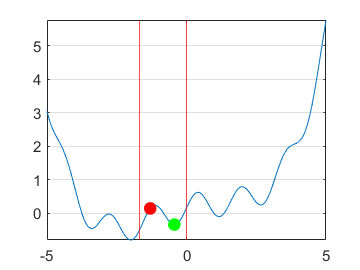

zew_min = -0.4354

iter = 11

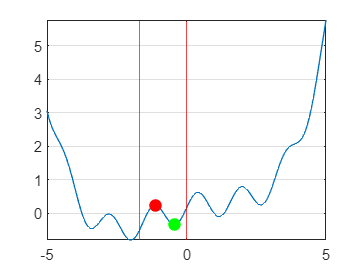

clear;
f = @(x) 0.2 * x + 0.4 * sin(4 * x) + (0.1 * x ^ 2 - 0.4) ^ 2;
x0_vec = [-1.3 -1.123]; eps = 0.001; ogr = [-1.7 0]; c0 = 2;

for x0 = x0_vec
    [zew_min, iter] = kar_wew(f, x0, c0, ogr(1), ogr(2), eps)
   

    figure; fplot(f); hold on; grid on;
    xline(ogr(1), 'r');
    xline(ogr(2), 'r');
    plot(x0, f(x0), 'ro', "MarkerSize", 7, "MarkerFace", "r");
    plot(zew_min, f(zew_min), 'go', "MarkerSize", 7, "MarkerFace", "g");
    hold off;
end

Funkcja kara zewnętrznej dla funkcji dwóch zmiennych

clear;
r = 0.5;
f_alt = @(x) 0.3 * x(1) + 0.1 * x(2) + (-3.5 + 0.5 * x(1) ^ 2 + 0.5 * x(2) ^ 2) ^ 2 + 100 * x(1) * exp(-x(1) ^ 2 - x(2) ^ 2);

x_max = fminsearch(@(x) -1 * f_alt(x), [0,0]);
x_min = fminsearch(@(x) f_alt(x), [0,0]);

f = @(x1, x2) f_alt([x1 x2]);

% Funcja kary jako stożek z miejscami zerowymi na okręgu o promieniu 0.5 ze
% środkiem w maksimum lokalnym funkcji f
g = @(x) sqrt((x(1) - x_max(1)) ^ 2 + (x(2) - x_max(2)) ^ 2) - 0.5;
S = @(x) max(0, g(x)) ^ 2;

figure;
fsurf(@(x1, x2) g([x1, x2]), [x_max(1) - r, x_max(1) + r, x_max(2) - r, x_max(2) + r]);

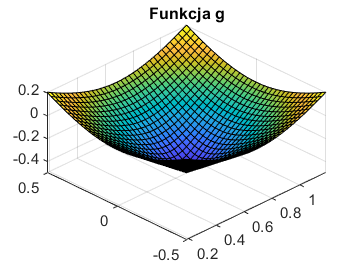

view([-3, -3, 5]);
title("Funkcja g");


figure;
fsurf(@(x1, x2) S([x1, x2]), [x_max(1) - r, x_max(1) + r, x_max(2) - r, x_max(2) + r]);

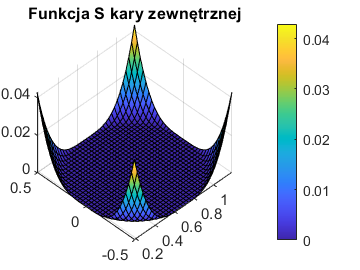

view([-3, -3, 5]);
title("Funkcja S kary zewnętrznej"); colorbar;


c0 = 2; eps = 0.001;

[zew_min, iter] = kar(f_alt, x_min, c0, S, eps)

zew_min =     0.1825    0.0008


iter = 17


figure; hold on;
r=0.5; teta=-pi:0.02:pi;
x=r*cos(teta) + x_max(1);
y=r*sin(teta) + x_max(2);
plot3(x,y,zeros(numel(x)) + 44, "r", LineWidth=2.5);
view([-3, -3, 5]); axis([-2.5 2.5 -2.5 2.5 -40 70]);
fsurf(f);

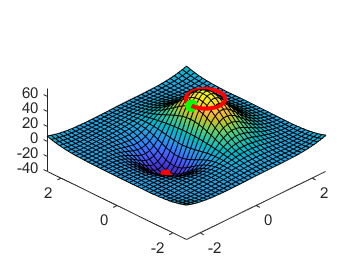

plot3(x_min(1), x_min(2), f(x_min(1), x_min(2)), 'ro', "MarkerSize", 7, "MarkerFace", "r");
plot3(zew_min(1), zew_min(2), 44, 'go', "MarkerSize", 7, "MarkerFace", "g");
hold off;


figure; hold on;
plot3(x,y,zeros(numel(x)) + 44, "r", LineWidth=2.5);
view(2); axis([x_min(1) - 0.1, x_max(1) + r + 0.1, x_max(2) - r - 0.1, x_max(2) + r + 0.1]);
fsurf(f);

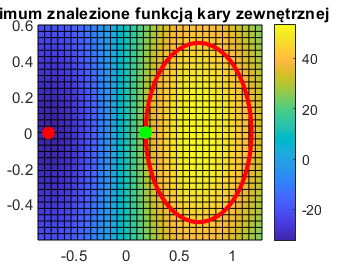

plot3(x_min(1), x_min(2), f(x_min(1), x_min(2)) + 1, 'ro', "MarkerSize", 7, "MarkerFace", "r");
plot3(zew_min(1), zew_min(2), 69, 'go', "MarkerSize", 7, "MarkerFace", "g");
title("Minimum znalezione funkcją kary zewnętrznej")
colorbar; hold off;

Funkcja kara wewnętrznej dla funkcji dwóch zmiennych

clear;
r = 0.5;
f_alt = @(x) 0.3 * x(1) + 0.1 * x(2) + (-3.5 + 0.5 * x(1) ^ 2 + 0.5 * x(2) ^ 2) ^ 2 + 100 * x(1) * exp(-x(1) ^ 2 - x(2) ^ 2);

x_max = fminsearch(@(x) -1 * f_alt(x), [0,0]);
x_min = fminsearch(@(x) f_alt(x), [0,0]);

f = @(x1, x2) f_alt([x1 x2]);

% Funcja kary jako stożek z miejscami zerowymi na okręgu o promieniu 0.5 ze
% środkiem w maksimum lokalnym funkcji f
g = @(x) sqrt((x(1) - x_max(1)) ^ 2 + (x(2) - x_max(2)) ^ 2) - 0.5;
S = @(x) -1 / g(x);

figure;
fsurf(@(x1, x2) g([x1, x2]), [x_max(1) - r, x_max(1) + r, x_max(2) - r, x_max(2) + r]);

view([-3, -3, 5]);
title("Funkcja g");


figure;
fsurf(@(x1, x2) S([x1, x2]), [x_max(1) - r, x_max(1) + r, x_max(2) - r, x_max(2) + r]);

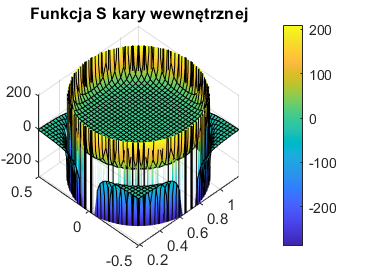

view([-3, -3, 5]);
title("Funkcja S kary wewnętrznej"); colorbar;


c0 = 3; eps = 0.001; alfa = 0.5;

[wew_min, iter] = kar2(f_alt, x_max, c0, S, eps, alfa)

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: -54043195528445992.000000 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: -27021597764223012.000000 



wew_min =     1.1832    0.0013


iter = 3


figure; hold on;
teta=-pi:0.02:pi;
x=r*cos(teta) + x_max(1);
y=r*sin(teta) + x_max(2);
plot3(x,y,zeros(numel(x)) + 44, "r", LineWidth=2.5);
view([-3, -3, 5]); axis([-2.5 2.5 -2.5 2.5 -40 70]);
fsurf(f);

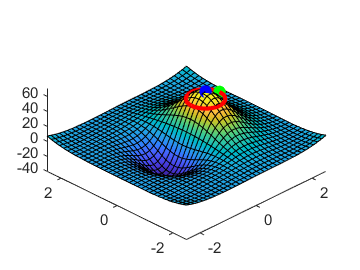

plot3(x_max(1), x_max(2), f(x_max(1), x_max(2)), 'bo', "MarkerSize", 7, "MarkerFace", "b");
plot3(wew_min(1), wew_min(2), 44, 'go', "MarkerSize", 7, "MarkerFace", "g");
hold off;


figure; hold on;
plot3(x,y,zeros(numel(x)) + 44, "r", LineWidth=2.5);
view(2); axis([x_max(1) - r - 0.1, x_max(1) + r + 0.1, x_max(2) - r - 0.1, x_max(2) + r + 0.1]);
fsurf(f);

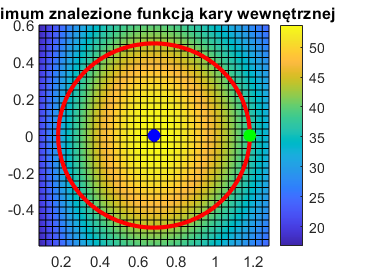

plot3(x_max(1), x_max(2), f(x_max(1), x_max(2)), 'bo', "MarkerSize", 7, "MarkerFace", "b");
plot3(wew_min(1), wew_min(2), 69, 'go', "MarkerSize", 7, "MarkerFace", "g");
title("Minimum znalezione funkcją kary wewnętrznej")
colorbar; hold off;